Plotting for ex 6.4

Optimization will be performed on end derivatives. This will improve optimization performance.
solving 1 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 2 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 3 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
Done!
Elapsed time is 0.301949 seconds.


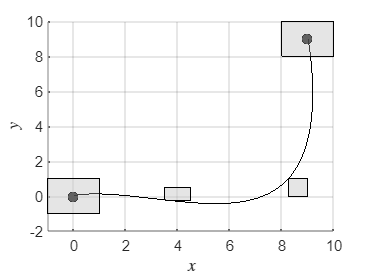

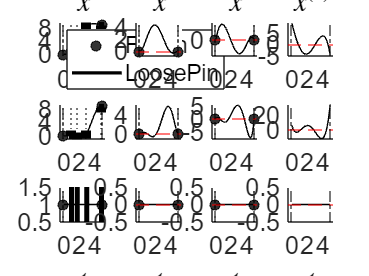

% Run scripts to get data.
uas_parameters;
uas_trajectory;

sim_result = sim("uas_main_6_4.slx", 10);

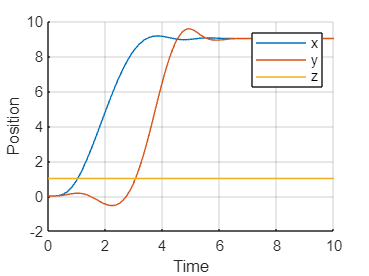

x = sim_result.simout.signals.values(1,:,:);
x = reshape(x, [length(x), 1]);
y = sim_result.simout.signals.values(2,:,:);
y = reshape(y, [length(y), 1]);
z = sim_result.simout.signals.values(3,:,:);
z = reshape(z, [length(z), 1]);
time = sim_result.tout;

figure
hold on
plot(time, x)
plot(time, y)
plot(time, z)
grid on
legend("x", "y", "z")
xlabel("Time")
ylabel("Position")
hold off

saveas(gcf, "ex_6_4.png")